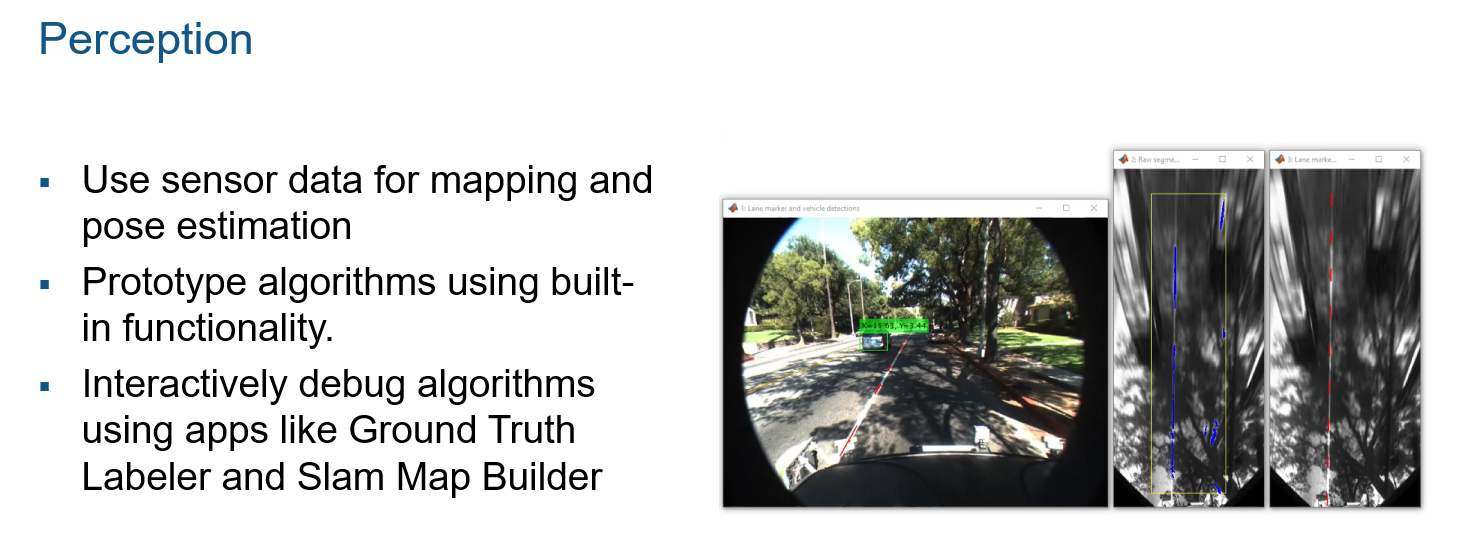

## Connecting MATLAB/Simulink to ROS

`rosinit` starts the global ROS node with a default MATLAB® name and tries to connect to a ROS master running on `localhost` and port `11311`. If the global ROS node cannot connect to the ROS master, `rosinit` also starts a ROS core in MATLAB, which consists of a ROS master, a ROS parameter server, and a rosout logging node.

rosshutdown

Shutting down global node /matlab_global_node_15972 with NodeURI http://192.168.1.132:57403/


rosinit 192.168.137.134

Initializing global node /matlab_global_node_25460 with NodeURI http://192.168.137.1:57624/


## Initialize subscriber

The `Subscriber` object created by the `rossubscriber` function represents a subscriber on the ROS network. The `Subscriber` object subscribes to an available topic or to a topic that it creates. This topic has an associated message type. Publishers can send messages over the network that the `Subscriber` object receives.

laserSub = rossubscriber('/scan');
receive(laserSub)

ans =   ROS LaserScan message with properties:

       MessageType: 'sensor_msgs/LaserScan'
            Header: [1×1 Header]
          AngleMin: -2.3562
          AngleMax: 2.3562
    AngleIncrement: 0.0044
     TimeIncrement: 0
          ScanTime: 0
          RangeMin: 0.1000
          RangeMax: 10
            Ranges: [1081×1 single]
       Intensities: [1081×1 single]

  Use showdetails to show the contents of the message


## Run SLAM

The `lidarSLAM` class performs simultaneous localization and mapping (SLAM) for lidar scan sensor inputs. The SLAM algorithm takes in lidar scans and attaches them to a node in an underlying pose graph. The algorithm then correlates the scans using scan matching. It also searches for loop closures, where scans overlap previously mapped regions, and optimizes the node poses in the pose graph.

maxLidarRange = 10;
mapResolution = 10;
slamAlg = lidarSLAM(mapResolution, maxLidarRange);
slamAlg.LoopClosureThreshold = 2;  
slamAlg.LoopClosureSearchRadius = 2;
scan=lidarScan(0,0);

for i=1:5
    %receive(laserSub);
    scan(i) = lidarScan(laserSub.LatestMessage);
    [isScanAccepted, loopClosureInfo, optimizationInfo] = addScan(slamAlg, scan(i));
    if isScanAccepted
        fprintf('Added scan %d \n', i);
        pause(2);
    end
end

Added scan 1 
Added scan 2 
Added scan 3 
Added scan 4 
Added scan 5 


## Plot scans and robot poses

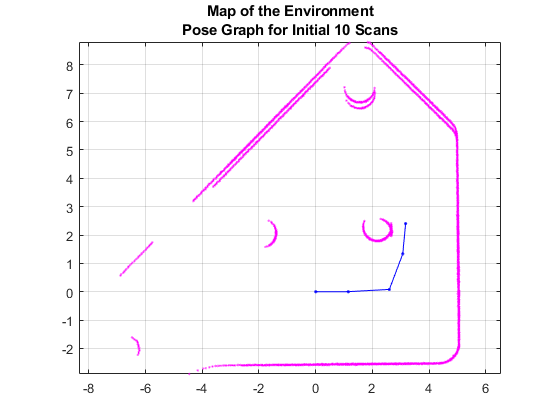

figure;
show(slamAlg);
title({'Map of the Environment','Pose Graph for Initial 10 Scans'});

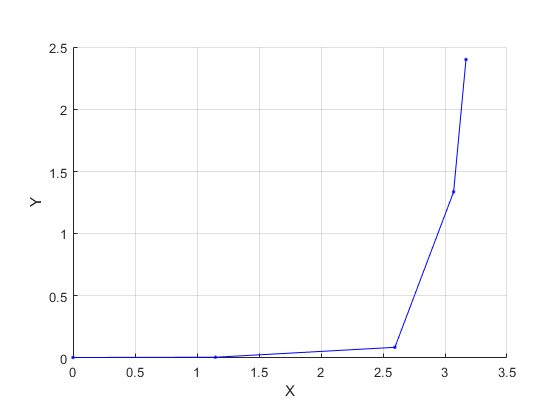

show(slamAlg.PoseGraph); 

### Interactively debug with Slam Map Builder

The **SLAM** **Map** **Builder** app loads recorded lidar scans and odometry sensor data to build a 2-D occupancy grid using simultaneous localization and mapping (**SLAM**) algorithms.

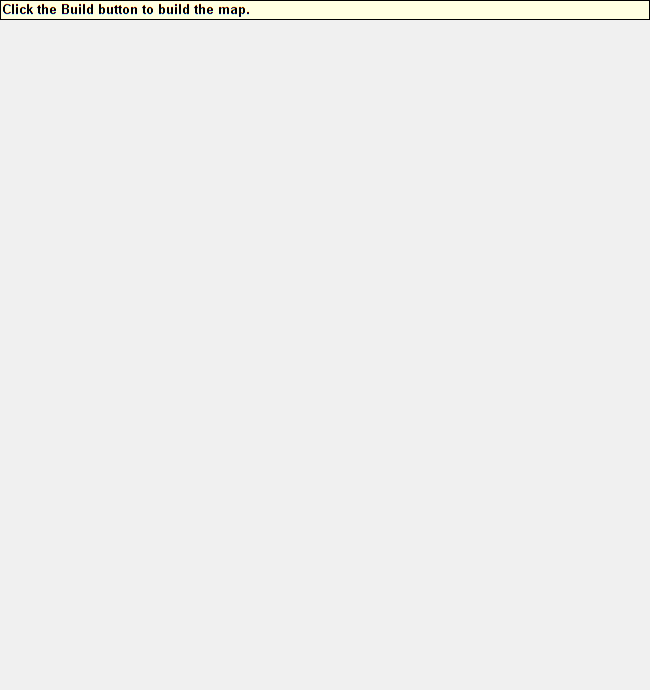

scans = num2cell(scan);
slamMapBuilder(scans);